# Summary of Alpha Values from VBWIM

% Search through VBResults and gather all 'All' alpha values! Scatter plot
clear, clc, close all

D = linspecer(30);  
%load('VBResultsAlpha60t.mat')
%load('VBResultsAlphaq(Q1=06etQ2=04)NEWLucas.mat')
load('VBResultsNew.mat')
Model = "SIA";
%if strcmp(Model,"ESIA")
  %VBR = VBResults.Monthly;
%else
%Model = "ESIA";
VBR = VBResults.(Model).Monthly;
%VBR = VBResults.(append('E',Model)).Monthly;
%VBR = VBResults.(Model).Monthly;
VBRDet = VBR(VBR.Traffic == 'Deterministic',:);
VBR = VBR(VBR.Traffic ~= 'Deterministic',:);
%end

VBR(VBR.Span == 2,:) = []; % remove 2 meters span
VBRDet(VBRDet.Span == 2,:) = []; % remove 2 meters span
%VBR(VBR.AE == "MxEdg" | VBR.AE == "MxMid",:) = []; % remove MxMid MxEdg from Slab
%VBR(VBR.Type == "Slab",:) = []; % remove Slab
VBR(VBR.Type == "Twin" & VBR.Span == 10,:) = []; % remove 10 meters Twin
St = [4 6 8 10 15 20 25 30 40 50 60 70 80]; % no 2 meters
%St = [4 5 6 8 10 15 20 25 30 40 50 60 70 80]; % no 2 meters
%St = [20 30 40 50 60 70 80]; % no 2 meters
Lab = {'4', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'}; % no 2 meters
%Lab = {'4', '5', '6', '8', '10', '15', '20', '25', '30', '40', '50', '60', '70', '80'}; % no 2 meters
%Lab = {'20', '30', '40', '50', '60', '70', '80'}; % no 2 meters
Fi = [1 2 3 4 5  6  7  8  9  10 11 12 13]; % no 2 meters
%Fi = [1 2 3 4 5  6  7  8  9  10 11 12 13 14]; % no 2 meters
%Fi = [1 2 3 4 5  6  7 ]; % no 2 meters

[~, idx] = ismember(VBR.Span,St);
xdataTr = Fi(idx);
[~, idxDet] = ismember(VBRDet.Span,St);
xdataTrDet = Fi(idxDet);

## Main Plot

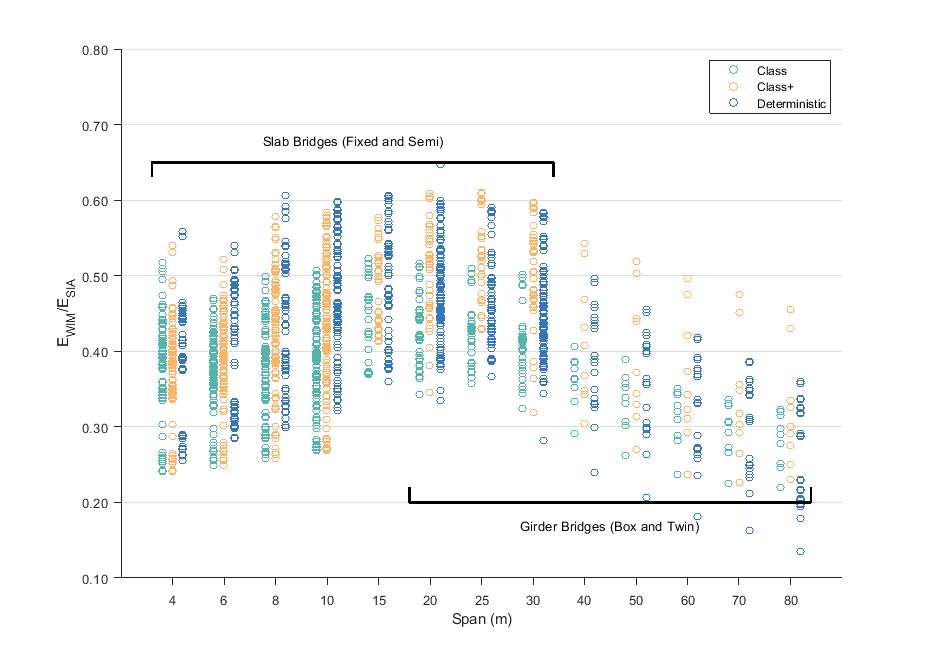

figure('Position',[325 225 930 650]); hold on;
%scatter(xdataTrSS+0.2,VBResults.SS.Monthly.All./1.15,30,[0.8 0.8 0.8],'DisplayName','StopSim');
%scatter(xdataTrSS,VBResults.SS.Monthly.ClassOW./1.15,30,[0.8 0.8 0.8],'HandleVisibility','off');
%scatter(xdataTrSS-0.2,VBResults.SS.Monthly.Class./1.15,30,[0.8 0.8 0.8],'HandleVisibility','off');

PlClass=scatter(xdataTr-0.2,VBR.Class,30,D(6,:),'DisplayName','Class');
PlClassOW=scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','Class+');
%PlClassOW=scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','Class+ Accompaniment (can be all)');
PlDeter=scatter(xdataTrDet+0.2,VBRDet.Class,30,D(3,:),'DisplayName','Deterministic');
%scatter(xdataTr-0.2,VBR.ClassOW,30,D(6,:),'DisplayName','Class+ Accompaniment');
%scatter(xdataTr,VBR.ClassOW,30,D(21,:),'DisplayName','% of q in ESIA');
%scatter(xdataTr(VBR.Type=="Box")-0.2,VBR.PropTrucks(VBR.Type=="Box").*100,30,D(6,:),'DisplayName','Box');
%scatter(xdataTr(VBR.Type=="Slab"),VBR.PropTrucks(VBR.Type=="Slab").*100,30,D(21,:),'DisplayName','Slab');
%scatter(xdataTr(VBR.Type=="Twin" & VBR.Span~=10)+0.2,VBR.PropTrucks(VBR.Type=="Twin" & VBR.Span~=10).*100,30,D(1,:),'DisplayName','Twin');
%{
load('VBResultsAlphaQ2.mat');
if strcmp(Model,"ESIA")
    VBR2 = VBResults.Monthly;
else
    VBR2 = VBResults.(Model).Monthly;
end
VBR2(VBR2.Span == 2,:) = [];
VBR2(VBR2.Type == "Twin" & VBR2.Span == 10,:) = [];
[~, idx2] = ismember(VBR2.Span,St);
xdataTr2 = Fi(idx2);
%s = scatter(xdataTr2+0.45,VBR2.All,30,D(1,:)+[0.3 0.3 0.3],"filled",'DisplayName','All LogNormal Fitting');
%s.MarkerFaceAlpha = 0.6;
%s = scatter(xdataTr2+0.15,VBR2.ClassOW,30,D(21,:)+[0.0 0.2 0.3],"filled",'DisplayName','Class+ LogNormal Fitting');
%s.MarkerFaceAlpha = 0.6;
s = scatter(xdataTr2,VBR2.ClassOW,30,D(21,:),'DisplayName','All Accompaniment');
s.MarkerFaceAlpha = 0.6;
%s = scatter(xdataTr2-0.15,VBR2.Class,30,D(6,:)+[0.25 0.15 0.1],"filled",'DisplayName','Class LogNormal Fitting');
%s.MarkerFaceAlpha = 0.6;
%}

xlim([0 max(Fi) + 1]); 
ylim([0.1 0.8])
%ylim([0 100])

ytickformat('%.2f');
%ytickformat('percentage');
yticks(0.1:0.1:0.8);
%yticks(0:10:100);
set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
xlabel('Span (m)')
%title('Monthly Block Maxima Summary')
ylabel(append('E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{qSIA}/E_{WIM}'))
%ylabel(append('E_{qSIA}/E_{(Q1+Q2+q)SIA}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('\fontsize{16} \bf\alpha_{q} \fontsize{11} \rm (with \alpha_{Q1} = 0.6 and \alpha_{Q2} = 0.4)        E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('% of Special Transport Monthly Maxima with Accompaniment'))
%legend('location','southwest')
legend('location','northeast')

% for finding the Infl Name
SpanName = int2str(VBR.Span);
SpanName((SpanName(:,1)==' '),1) = '0';
SpanName = strcat('S',SpanName);
InflName = VBR.Type + '.' + VBR.SubType + '.' + VBR.Width + '.' + VBR.Layout + '.' + VBR.Support + '.' + VBR.Trans + '.' + VBR.AE + '.' + SpanName;
SpanNameDet = int2str(VBRDet.Span);
SpanNameDet((SpanNameDet(:,1)==' '),1) = '0';
SpanNameDet = strcat('S',SpanNameDet);
InflNameDet = VBRDet.Type + '.' + VBRDet.SubType + '.' + VBRDet.Width + '.' + VBRDet.Layout + '.' + VBRDet.Support + '.' + VBRDet.Trans + '.' + VBRDet.AE + '.' + SpanNameDet;
row = dataTipTextRow('Infl',InflName);
rowdet = dataTipTextRow('Infl',InflNameDet);
PlClass.DataTipTemplate.DataTipRows(end+1) = row;
PlClassOW.DataTipTemplate.DataTipRows(end+1) = row;
PlDeter.DataTipTemplate.DataTipRows(end+1) = rowdet;
PlClass.DataTipTemplate.DataTipRows(1).Value = VBR.Span;
PlClassOW.DataTipTemplate.DataTipRows(1).Value = VBR.Span;
PlDeter.DataTipTemplate.DataTipRows(1).Value = VBRDet.Span;

% for Ebru comparison
%ylucas = [1.68,1.98,1.57,1.75,1.83,1.87,1.86,1.82,1.74,1.31,1.21,1.12,1.09,1.07];
%ylucas = [1.98,1.57,1.75,1.83,1.87,1.86,1.82,1.74,1.31,1.21,1.12,1.09,1.07];
%ylucas2 = [1.38,1.84,1.52,1.77,1.85,1.90,1.87,1.84,1.76,1.27,1.16,1.04,0.95,0.87];
%ylucas2 = [1.84,1.52,1.77,1.85,1.90,1.87,1.84,1.76,1.27,1.16,1.04,0.95,0.87];
%plot(Fi,ylucas,'Color',D(1,:),'LineStyle',"--","LineWidth",1,'DisplayName','OriginalAll');
%plot(Fi,ylucas2,'Color',D(21,:),'LineStyle',"--","LineWidth",1,'DisplayName','OriginalClass+');

%{%
yh = 0.65; %0.85
line([0.6,0.6,8.4,8.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
text(4.5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
yh = 0.2; %0.15
line([5.6,5.6,13.4,13.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
text(9.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')

%}


## Selectable Plot

% Refine VBR Based on checkboxes
LBox = VBR.Type == 'Box';
LTwin = VBR.Type == 'Twin';
LSlab = VBR.Type == 'Slab';
LMulti = VBR.Type == 'Multi';

LBoxDet = VBRDet.Type == 'Box';
LTwinDet = VBRDet.Type == 'Twin';
LSlabDet = VBRDet.Type == 'Slab';
LMultiDet = VBRDet.Type == 'Multi';

LMp = VBR.AE == 'Mp';
LMn = VBR.AE == 'Mn';
LV = VBR.AE == 'V';
LMxEdg = VBR.AE == 'MxEdg';
LMxMid = VBR.AE == 'MxMid';

LMpDet = VBRDet.AE == 'Mp';
LMnDet = VBRDet.AE == 'Mn';
LVDet = VBRDet.AE == 'V';
LMxEdgDet = VBRDet.AE == 'MxEdg';
LMxMidDet = VBRDet.AE == 'MxMid';

Lp0 = VBR.Trans == 'p0';
Lp1 = VBR.Trans == 'p1';
Lp2 = VBR.Trans == 'p2';
Lp3 = VBR.Trans == 'p3';

Lp0Det = VBRDet.Trans == 'p0';
Lp1Det = VBRDet.Trans == 'p1';
Lp2Det = VBRDet.Trans == 'p2';
Lp3Det = VBRDet.Trans == 'p3';

LUni2L = VBR.Traffic == 'Uni2L';
LBi2L = VBR.Traffic == 'Bi2L';
LBi4L = VBR.Traffic == 'Bi4L';

### Type

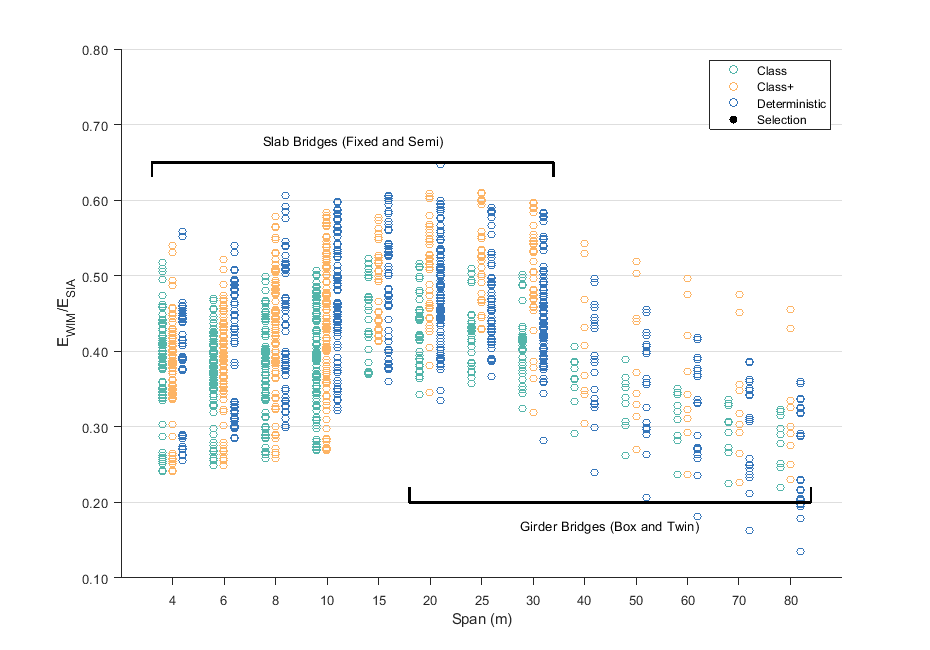

Box = false;
Twin = false;
Slab = false;
Multi = false;

% Update logical
Log = any([Box*LBox Twin*LTwin Slab*LSlab Multi*LMulti],2);
LogDet = any([Box*LBoxDet Twin*LTwinDet Slab*LSlabDet Multi*LMultiDet],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
xdDet = xdataTrDet(LogDet) + 0.2;
VBRPlot = VBRDet.Class(LogDet);
try delete(h1); end
h1 = scatter(xdDet,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Action Effect

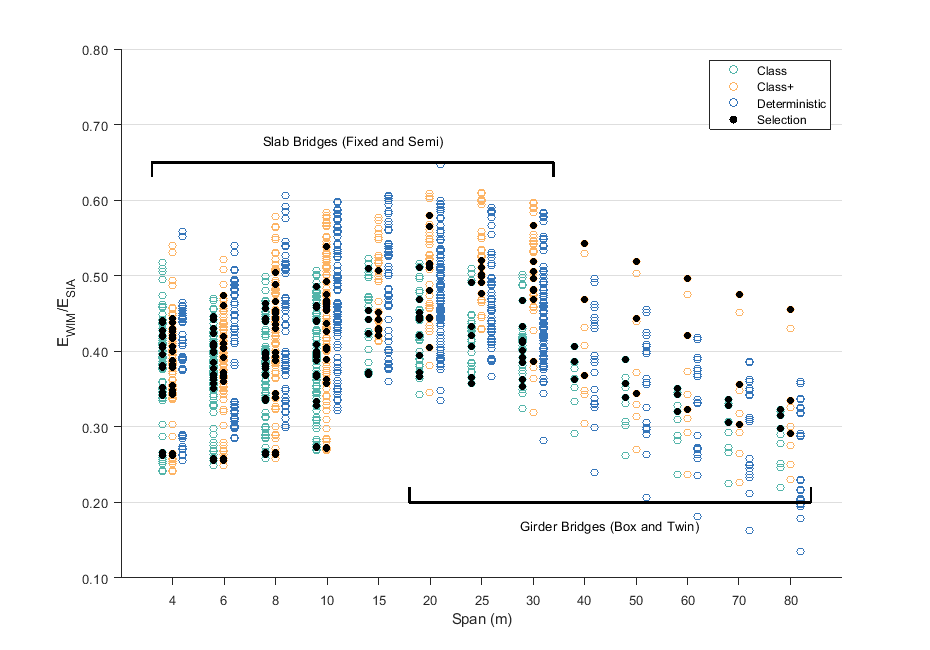

Mn = false;
Mp = false;
V = true;
MxEdg = false;
MxMid = false;

% Update logical
Log = any([Mn*LMn Mp*LMp V*LV MxEdg*LMxEdg MxMid*LMxMid],2);
% Combine Logicals to get master logical
%xd = xdataTr(Log) + 0.2;
%VBRPlot = VBR.All(Log);
%try delete(h1); end
%h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Transverse Location

p0 = false;
p1 = false;
p2 = false;
p3 = false;

% Update logical
Log = any([p0*Lp0 p1*Lp1 p2*Lp2 p3*Lp3],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Transverse Location

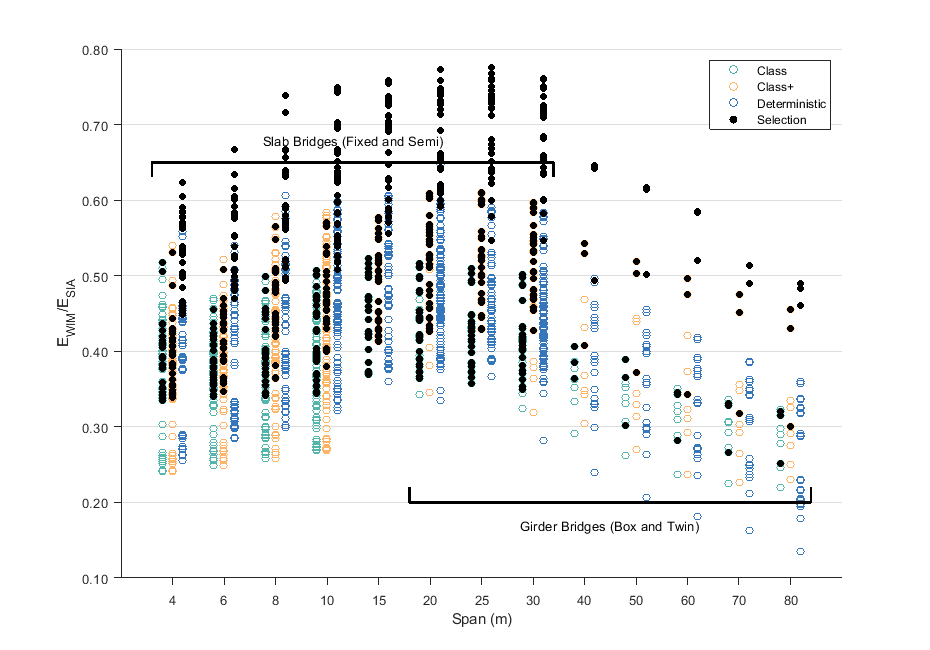

Uni2L = true;
Bi2L = false;
Bi4L = false;

% Update logical
Log = any([Uni2L*LUni2L Bi2L*LBi2L Bi4L*LBi4L],2);
% Combine Logicals to get master logical
xd = xdataTr(Log) + 0.2;
VBRPlot = VBR.All(Log);
try delete(h1); end
h1 = scatter(xd,VBRPlot,30,'k','filled','DisplayName','Selection');
xd = xdataTr(Log);
VBRPlot = VBR.ClassOW(Log);
try delete(h2); end
h2 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');
xd = xdataTr(Log) - 0.2;
VBRPlot = VBR.Class(Log);
try delete(h3); end
h3 = scatter(xd,VBRPlot,30,'k','filled','HandleVisibility','off');

### Colors for Best Fits

ColorPlot = false;

if ColorPlot
clf

%try delete(h1); end
%h1 = scatter([],[],30,'k','filled','HandleVisibility','off');
%try delete(h2); end
%h2 = scatter([],[],30,'k','filled','HandleVisibility','off');
%try delete(h3); end
%h3 = scatter([],[],30,'k','filled','HandleVisibility','off');

scatter(xdataTr(VBR.BestFitClassOW=='Lognormal'),VBR.ClassOW(VBR.BestFitClassOW=='Lognormal'),30,D(13,:),'filled','DisplayName','Class+ Lognormal');
hold on;
scatter(xdataTr(VBR.BestFitClassOW=='LognormalTF'),VBR.ClassOW(VBR.BestFitClassOW=='LognormalTF'),30,D(10,:),'filled','DisplayName','Class+ LognormalTF');
scatter(xdataTr(VBR.BestFitClassOW=='Normal'),VBR.ClassOW(VBR.BestFitClassOW=='Normal'),30,D(7,:),'filled','DisplayName','Class+ Normal');
scatter(xdataTr(VBR.BestFitClassOW=='gev'),VBR.ClassOW(VBR.BestFitClassOW=='gev'),30,D(4,:),'DisplayName','Class+ gev');
scatter(xdataTr(VBR.BestFitClassOW=='gevGumbel'),VBR.ClassOW(VBR.BestFitClassOW=='gevGumbel'),30,D(1,:),'DisplayName','Class+ gevGumbel');
%scatter(xdataTr-0.2,VBR.ClassOW,30,D(6,:),'DisplayName','Class+ Accompaniment');
scatter(xdataTr(VBR.BestFitClass=='Lognormal')-0.2,VBR.Class(VBR.BestFitClass=='Lognormal'),30,D(18,:),'filled','DisplayName','Class Lognormal');
scatter(xdataTr(VBR.BestFitClass=='LognormalTF')-0.2,VBR.Class(VBR.BestFitClass=='LognormalTF'),30,D(21,:),'filled','DisplayName','Class LognormalTF');
scatter(xdataTr(VBR.BestFitClass=='Normal')-0.2,VBR.Class(VBR.BestFitClass=='Normal'),30,D(24,:),'filled','DisplayName','Class Normal');
scatter(xdataTr(VBR.BestFitClass=='gev')-0.2,VBR.Class(VBR.BestFitClass=='gev'),30,D(27,:),'DisplayName','Class gev');
scatter(xdataTr(VBR.BestFitClass=='gevGumbel')-0.2,VBR.Class(VBR.BestFitClass=='gevGumbel'),30,D(30,:),'DisplayName','Class gevGumbel');
xlim([0 max(Fi) + 1]); 
ylim([0.0 1.0])
%ylim([0 100])

ytickformat('%.2f');
%ytickformat('percentage');
yticks(0.0:0.1:1.0);
%yticks(0:10:100);
set(gca,'TickDir','out');
set(gca,'YGrid','on');
xticks(Fi);
xticklabels(Lab);
xlabel('Span (m)')
%title('Monthly Block Maxima Summary')
ylabel(append('E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('E_{qSIA}/E_{WIM}'))
%ylabel(append('E_{qSIA}/E_{(Q1+Q2+q)SIA}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{',erase(Model,'E'),'}'))
%ylabel(append('\fontsize{16} \bf\alpha_{Q2} \fontsize{11} \rm (with \alpha_{Q1} = 0 and \alpha_{q} = 0.5)        E_{WIM}/E_{SPTR}'))
%ylabel(append('% of Special Transport Monthly Maxima with Accompaniment'))
%legend('location','southwest')
legend('location','northeast')

yh = 0.7; %0.85
line([0.6,0.6,8.4,8.4],[yh-0.02,yh,yh,yh-0.02,],'Color','k','LineWidth',2,'HandleVisibility','off')
text(4.5,yh+0.03,'Slab Bridges (Fixed and Semi)','HorizontalAlignment','center')
yh = 0.10; %0.15
line([5.6,5.6,13.4,13.4],[yh+0.02,yh,yh,yh+0.02],'Color','k','LineWidth',2,'HandleVisibility','off')
text(9.5,yh-0.03,'Girder Bridges (Box and Twin)','HorizontalAlignment','center')
end

